BRAYAN, GABRIEL, ALEXANDER, BETZY, EFRAIN

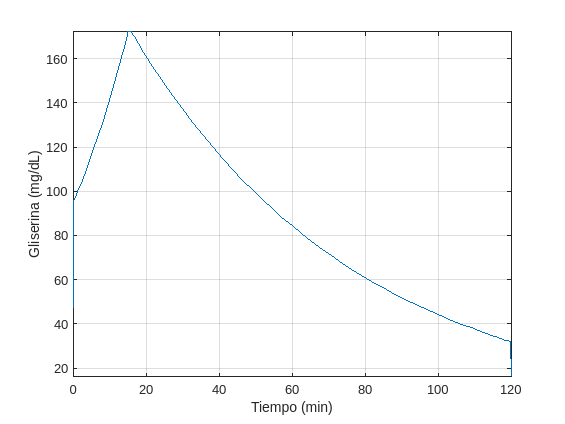

clc
clear all
close all
syms t

%Funciones a trozos
y1=95*exp(0.0395*t);
y2=172;
y3=172*exp(-0.01617*(t-16));

%Los puntos criticos 

v1=y1*heaviside(t);
v2=(y2-y1)*heaviside(t-15);
v3=(y3-y2)*heaviside(t-16);
v4=-y3*heaviside(t-120);
Y=v1+v2+v3+v4;
fplot(Y,[0 120])

xlabel('Tiempo (min)')
ylabel('Gliserina (mg/dL)')
 grid on